# Step 10: 連続潮流計算

連続潮流計算は、平衡点から負荷を少しずつ大きくしながら潮流解をたどり、PV カーブとノーズ点（最大負荷点）を求める計算です。この Step では、`calculate_continuation_powerflow` の呼び出し方、ノーズ点の読み方、PV カーブの描き方、刻み幅の調整、運転制約の扱い、結果の書き出しを順に扱います。

この Step は、GUILDA の基本的な流れの赤枠の部分です。

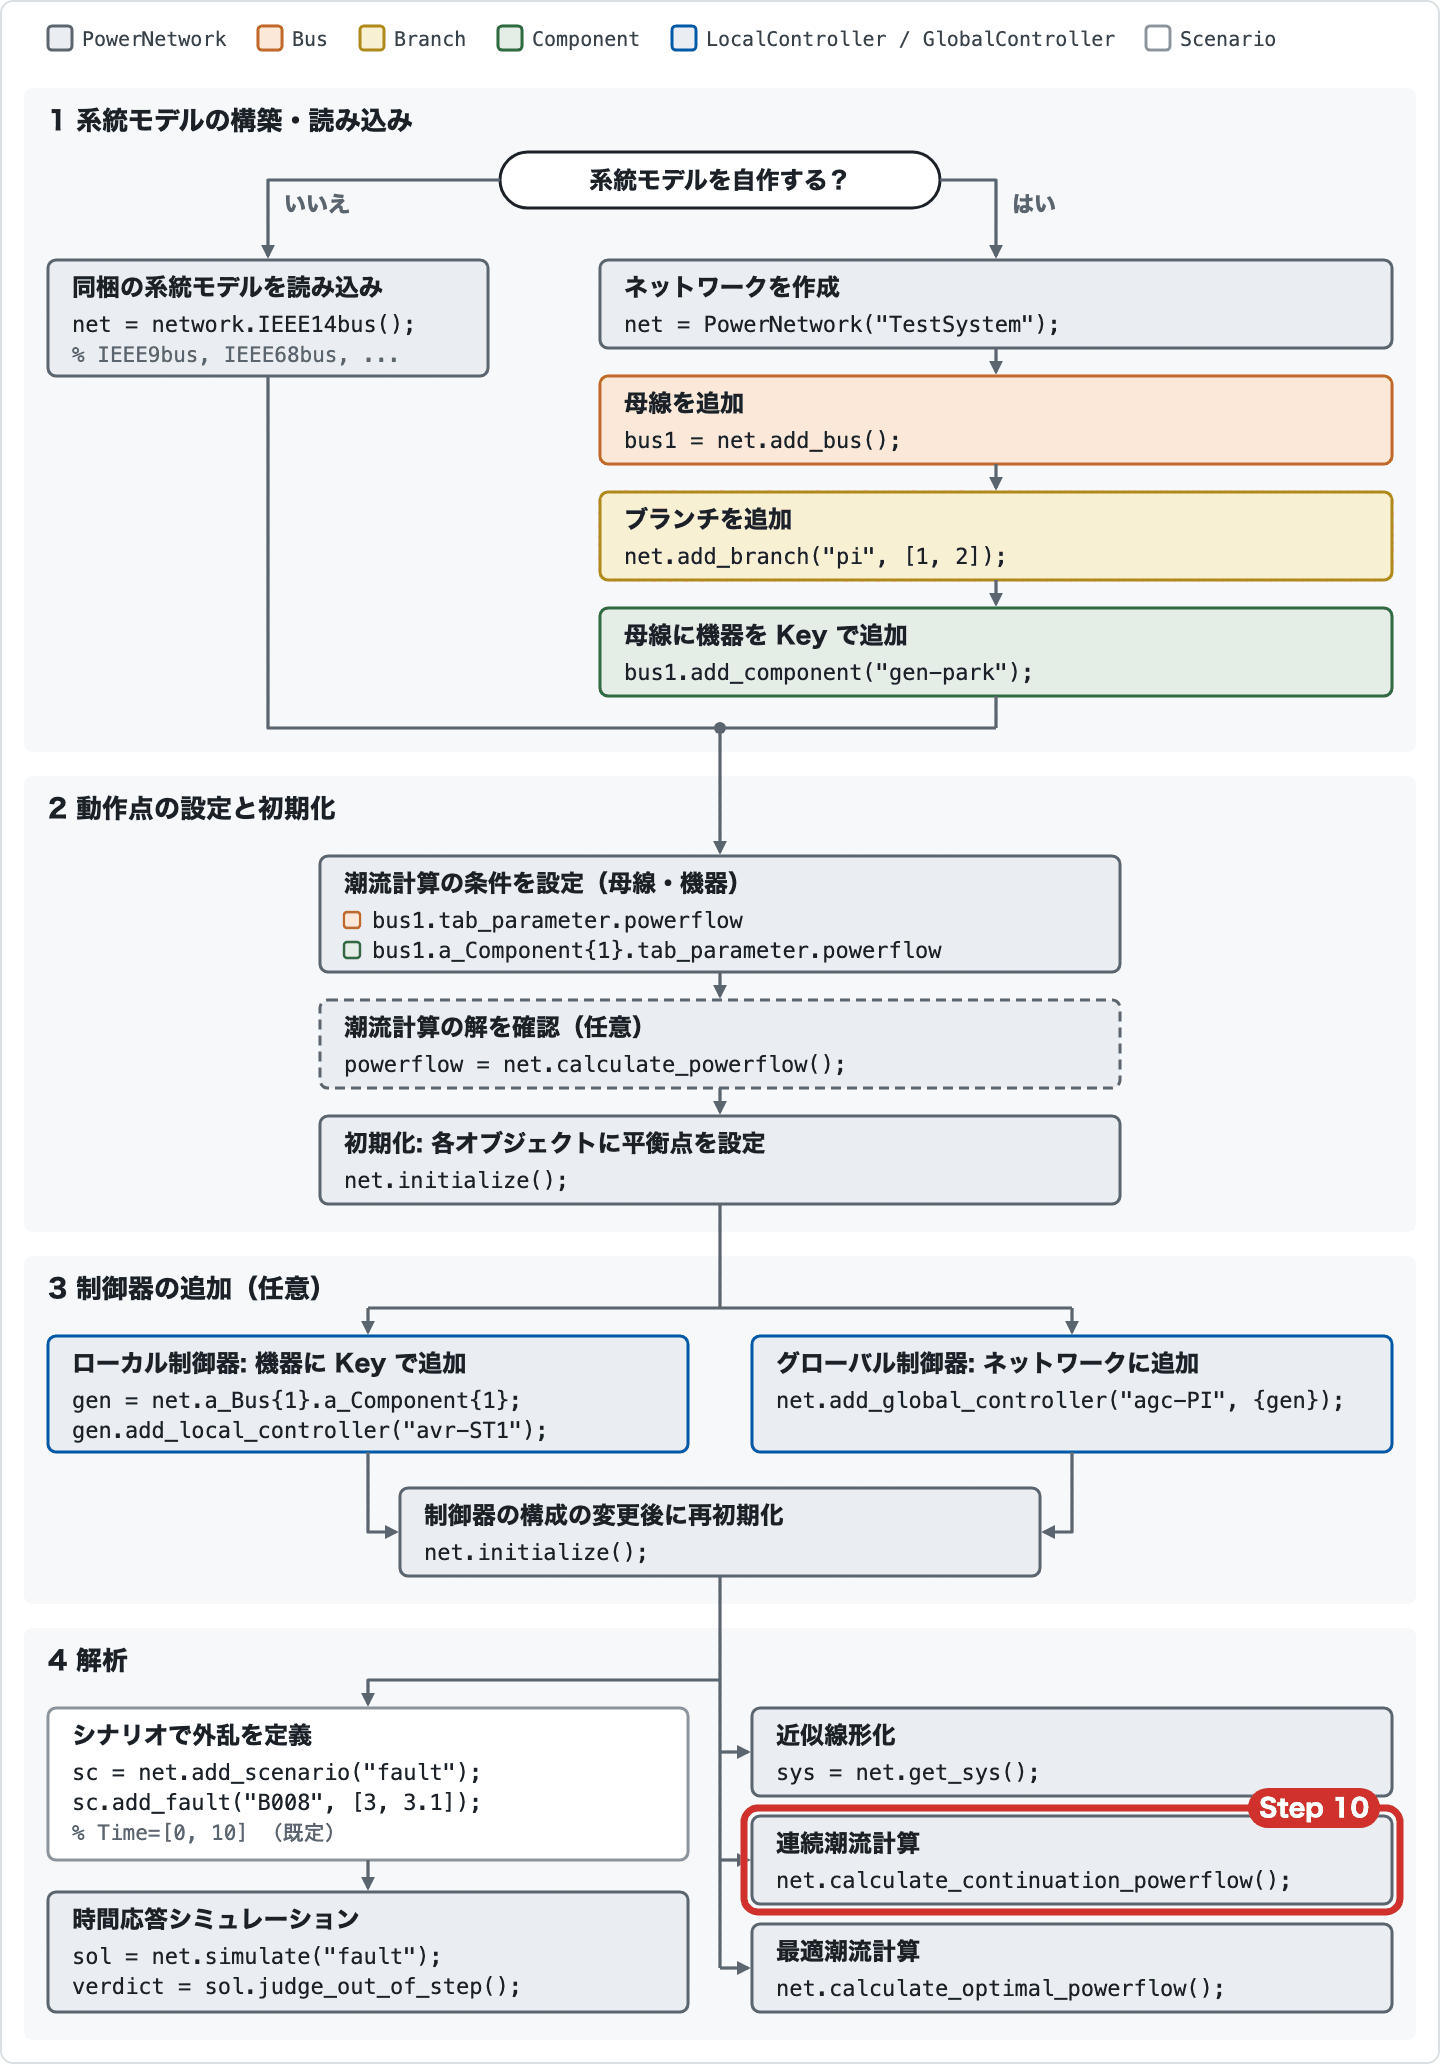

**この Step で分かること**

- `net.calculate_continuation_powerflow` の実行と、負荷を増やす母線の指定（`LoadBus`、`net.solver_CPF`）

- ノーズ点の λ（`r_lambdaMax`）の読み方と、結果 `ResultCPF` の中身

- `plot_pvcurve` による PV カーブの描画

- 刻み幅（`StepSize`、`ArcLength`）と最大ステップ数（`MaxIteration`）の調整

- 運転制約を守る計算（`Limits`）

- 結果のファイルへの書き出し（`export`、`Export`）

各節は、系統を用意して計算し、結果を出すのに要るコードだけで進みます。**確かめる（省略できます）** の下のコードは、中身を見るためのものです。飛ばしても最後まで動きます。

連続潮流計算の考え方（PV カーブ、ノーズ点、予測子・修正子法）は、[講義ノート Part 7](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part7-continuation-power-flow.html","-browser"))（ブラウザで開きます）で説明しています。

## 1. 系統を準備する

連続潮流計算は `net.initialize` で求めた平衡点から出発します。IEEE 9 母線系統を読み込み、平衡点を求めます。

net = network.IEEE9bus(LocalController=true);
[~, flag_init] = net.initialize()

flag_init = 1

`flag_init` が 1 なら準備ができています。負荷は母線 5・6・8 にあります。

**注意:** `initialize` の後で系統を編集した（平衡点が古くなった）ときに連続潮流計算を呼ぶと、`net.initialize()` の実行を促すエラーで止まります。運転制約（`tab_parameter.operation`）の編集は平衡点を変えないので、`initialize` をやり直す必要はありません。

## 2. 連続潮流計算を実行する

`LoadBus` に負荷を増やす母線のタグを渡して実行します。指定した母線にある機器の電力が、同じ倍率 (1 + λ) で大きくなります。戻り値は、結果 `result`、成否 `flag`、詳細 `output` の 3 つです。

[result, flag, output] = net.calculate_continuation_powerflow(LoadBus=["B005","B006","B008"]);
flag

flag = logical
   1


`flag` が 1 なら、ノーズ点を越えて経路をたどれています。

**注意:** 計算が 0.5 秒以上続くと、進捗のダイアログが開きます。進捗の表示や途中経過の表示、計算中のライブ表示を選ぶオプションなど、その他のオプションは `calculate_continuation_powerflow` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=calculate_continuation_powerflow')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

**確かめる（省略できます）**

`output.message` に、ノーズ点の λ と、何ステップ目で越えたかが書かれます。`output.correctorIterations` は各ステップで修正子が要した反復回数です。

output.message

ans = "The path passed the nose at lambda = 1.37392 (step 90 of 207)."

結果 `result` は `ResultCPF` オブジェクトです。表示すると、プロパティの一覧が並びます。

result

result =   ResultCPF のプロパティ:

           sv_bus: [9×1 string]
        rv_lambda: [0 0.0223 0.0446 0.0668 0.0890 0.1111 0.1332 0.1552 0.1771 0.1989 0.2207 0.2425 0.2641 0.2857 0.3072 0.3287 0.3500 0.3713 0.3924 0.4135 0.4345 0.4554 0.4762 0.4969 0.5175 0.5380 0.5583 0.5786 0.5987 0.6187 0.6386 … ] (1×208 double)
          cm_Vbus: [9×208 double]
      r_lambdaMax: 1.3739
       r_noseStep: 91
             rm_x: [19×208 double]
    rm_xPredicted: [19×208 double]
       tab_switch: [0×5 table]
         tab_stop: [0×6 table]
     tab_variable: [72×8 table]
      rm_variable: [208×72 double]
    cm_Icomponent: [6×208 double]
      sct_network: [1×1 struct]
      rv_sigmaMin: [0.9614 0.9593 0.9571 0.9547 0.9523 0.9496 0.9469 0.9440 0.9410 0.9378 0.9345 0.9310 0.9274 0.9237 0.9198 0.9158 0.9116 0.9072 0.9028 0.8981 0.8933 0.8883 0.8832 0.8779 0.8725 0.8669 0.8611 0.8551 0.8490 0.8427 0.8362 … ] (1×208 double)
      tab_weakbus: [9×3 table]
        r_marginP: 4.3278
         tab_nose: [9×3 tab

主なプロパティは次のとおりです（読み方は 3 節）。

- `rv_lambda`・`cm_Vbus`・`sv_bus`: 経路の各点の λ と母線電圧（複素数、1 行が 1 母線で、行の並びは `sv_bus` の順）

- `r_lambdaMax`・`r_noseStep`・`tab_nose`: ノーズ点の λ、その点の番号、その点の母線電圧

- `tab_path`: 経路の全点を 1 行ずつ並べた表

- `tab_switch`・`tab_stop`: 運転制約による切り替えと打ち切り（7 節）

- `rv_sigmaMin`・`tab_weakbus`・`r_marginP`: 電圧安定性の指標（潮流のヤコビ行列の最小特異値、ノーズ点で弱い母線の順位、有効電力で表した負荷の余裕）

- `tab_variable`・`rm_variable`・`cm_Icomponent`: 各点の動作点（機器と制御器の状態・入力、機器の電流）

## 3. ノーズ点を読む

ノーズ点の λ が `r_lambdaMax` です。負荷は元の (1 + λ) 倍なので、`1 + r_lambdaMax` が供給できる負荷の倍率です。

lambda_max = result.r_lambdaMax

lambda_max = 1.3739

**確かめる（省略できます）**

経路の点の数と母線の並びです。最初の点（λ = 0）が元の負荷の平衡点です。

size(result.rv_lambda)

ans =      1   208


size(result.cm_Vbus)

ans =      9   208


result.sv_bus.'

ans = 1×9 の string 配列
    "B001"    "B002"    "B003"    "B004"    "B005"    "B006"    "B007"    "B008"    "B009"


ノーズ点の番号 `r_noseStep` と、その点の母線電圧 `tab_nose`（大きさ `V`、位相 `Varg`、複素数 `Vphasor`）です。

result.r_noseStep

ans = 91

result.tab_nose

ans = 9×3 table
               V         Varg          Vphasor     
            _______    ________    ________________

    B001       1.04           0       1.04+0i      
    B002      1.025    -0.74922    0.75053-0.69809i
    B003      1.025    -0.81573    0.70247-0.74643i
    B004    0.80877    -0.38762    0.74877-0.3057i 
    B005    0.66908     -0.8453    0.44394-0.50058i
    B006    0.73528    -0.76737    0.52921-0.51046i
    B007    0.90866    -0.85882    0.59366-0.68792i
    B008     0.8642     -0.9842    0.47836-0.71973i
    B009    0.93225    -0.86788    0.60265-0.71127i


経路の全点を 1 行ずつ並べた表 `tab_path` です。列は `lambda` と、各母線の `V_<母線>`・`Varg_<母線>` です。

head(result.tab_path(:, ["lambda","V_B005","V_B006","V_B008"]), 5)

     lambda     V_B005     V_B006    V_B008
    ________    _______    ______    ______

           0    0.99563    1.0127    1.0159
     0.02233    0.99413    1.0114    1.0147
    0.044603     0.9926    1.0101    1.0136
    0.066825    0.99103    1.0088    1.0124
    0.088993    0.98942    1.0075    1.0112



ノーズ点で電圧が弱い母線の順位 `tab_weakbus` と、有効電力で表した負荷の余裕 `r_marginP` [pu] です。`Participation` が大きい母線ほど、ノーズ点付近で電圧が崩れやすい母線です。

result.tab_weakbus

ans = 9×3 table
     Bus      Participation    dVdLambda
    ______    _____________    _________

    "B005"             1        -0.23768
    "B006"       0.80843        -0.20189
    "B004"       0.69827        -0.15796
    "B008"       0.29851         -0.1104
    "B007"       0.28968       -0.085239
    "B009"       0.24463       -0.072857
    "B001"             0               0
    "B002"             0               0
    "B003"             0               0


result.r_marginP

ans = 4.3278

**注意:** `rm_x` は計算で使った変数ベクトルそのもの（各母線の [|V|; ∠V] と、最後の行が λ）、`rm_xPredicted` は予測子が出した点です。予測子・修正子法の動きを調べるときに使います。

## 4. 負荷を増やす母線を系統に記憶させる

呼び出しで渡した `LoadBus` は、その呼び出しにだけ効きます。毎回同じ母線を使うときは、ソルバー `net.solver_CPF` の `LoadBus` に設定しておくと、次の呼び出しから省略できます。

net.solver_CPF.LoadBus = ["B005","B006","B008"];
result = net.calculate_continuation_powerflow();

**注意:** `LoadBus` を一度も指定せずに呼ぶと、母線の指定を求めるエラーになります。また、`net.reset_solver` で `net.solver_CPF` を作り直すと、`LoadBus` は空に戻ります。

**確かめる（省略できます）**

ソルバーの設定と、その計算で実際に使った設定 `result.options` を表示します。

net.solver_CPF

ans =   SolverCPF のプロパティ:

    LoadBus: ["B005"    "B006"    "B008"]


result.options.LoadBus

ans = 1×3 の string 配列
    "B005"    "B006"    "B008"


## 5. PV カーブを描く

`plot_pvcurve` で、母線電圧の大きさを λ に対して描きます。既定では `LoadBus` の母線を描き、破線がノーズ点です。

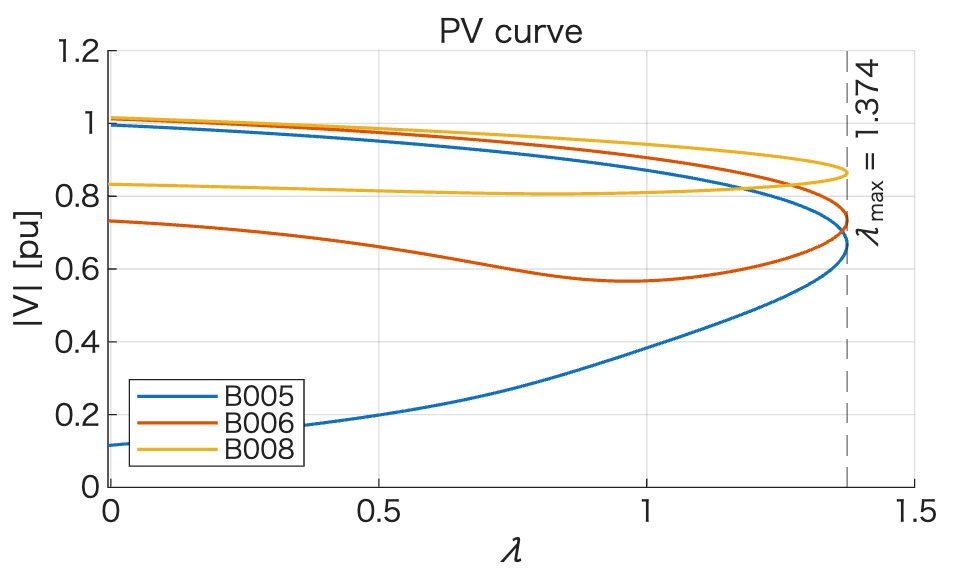

G = result.plot_pvcurve();

`Bus` で描く母線を選べます。`"all"` ならすべての母線です。戻り値 `G` は図のオブジェクト（`GraphChart`）で、`set_style` で線ごとに色や太さを変えられます。

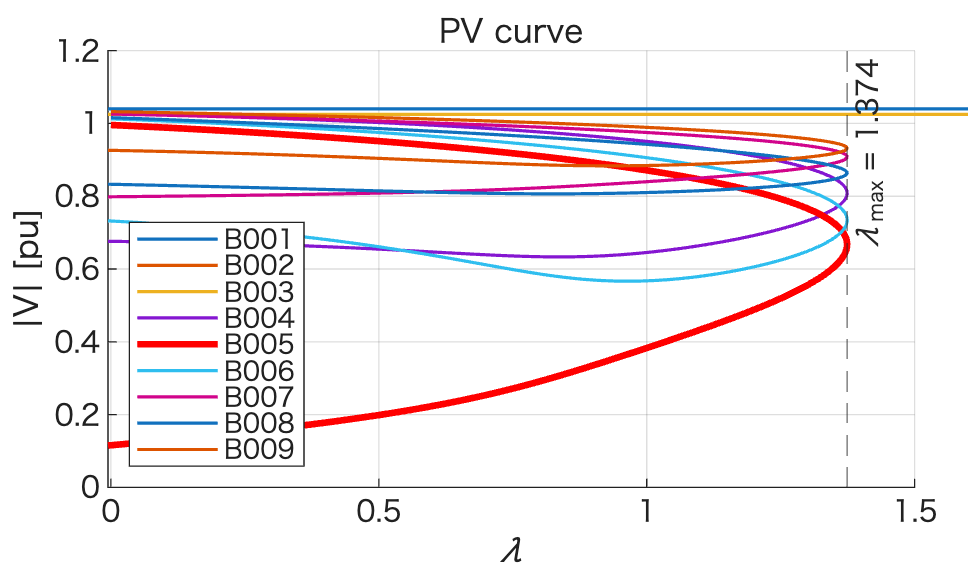

G = result.plot_pvcurve(Bus="all");
G.set_style("B005", Color="r", LineWidth=2.5);

母線 5 の線が赤く太くなりました。電圧がいちばん大きく下がるのは負荷の最も大きい母線 5 です。発電機のある母線 1〜3 の電圧は、最後まで一定です。

描く先の figure や axes を選ぶオプションなど、その他のオプションは `plot_pvcurve` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=ResultCPF&method=plot_pvcurve')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

## 6. 刻み幅とステップ数を調整する

1 ステップの進み方は、予測子の係数 `StepSize`（既定 0.5）と修正子の弧長 `ArcLength`（既定 1e-3）で決まります。大きくすると点が粗くなり、早く終わります。

result_coarse = net.calculate_continuation_powerflow(StepSize=1, ArcLength=1e-2);

`MaxIteration`（既定 500）はステップ数の上限です。上限に達するまでにノーズ点を越えられないと、`flag` は 0 になります。

[~, flag_short, output_short] = net.calculate_continuation_powerflow(MaxIteration=40);
flag_short

flag_short = logical
   0


収束判定や出発点の λ など、その他のオプションは `calculate_continuation_powerflow` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=calculate_continuation_powerflow')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

**確かめる（省略できます）**

既定の刻みと粗い刻みで、点の数とノーズ点の λ を比べます。

[numel(result.rv_lambda), numel(result_coarse.rv_lambda)]

ans =    208    67


[result.r_lambdaMax, result_coarse.r_lambdaMax]

ans =     1.3739    1.3733


点の数は約 3 分の 1 になり、ノーズ点の λ はほとんど変わりません。ただし点が粗いと、ノーズ点付近の形は荒くなります。

上限で止まったときは、`output.message` が対処を示します。

output_short.message

ans = "The path did not pass the nose within 40 steps (largest lambda = 0.829496). Increase MaxIteration or StepSize."

## 7. 運転制約を守って計算する

`Limits` を指定すると、機器・母線・ブランチの運転制約（`tab_parameter.operation`）を守りながら経路をたどります。指定できるのは `"Q"`、`"V"`、`"S"` の組み合わせと、`"all"`、`"none"`（既定）です。

### 無効電力の上限（"Q"）

発電機の運転制約は `net.get_parameter("operation", Key=...)` で、発電機 1 つにつき 1 行の表として読めます。無効電力の上下限 `Qmin`・`Qmax` は `-Inf`・`Inf`（制約なし）です。発電機 2 と 3 の `Qmax` に 0.6 pu を設定し（この例のための値です）、`net.set_parameter` で書き戻して計算します。最初に読んだ表 `tab_gen0` は、後で元に戻すために取っておきます。

tab_gen0 = net.get_parameter("operation", Key="gen-1axis");
tab_gen = tab_gen0;
tab_gen{["B002SG1", "B003SG1"], "Qmax"} = 0.6;
net.set_parameter("operation", tab_gen);
result_Q = net.calculate_continuation_powerflow(Limits="Q");

**確かめる（省略できます）**

書き戻した後の発電機の運転制約です。

net.get_parameter("operation", Key="gen-1axis")

ans = 3×5 table
               baseMVA    Pmin    Pmax    Qmin    Qmax
               _______    ____    ____    ____    ____

    B001SG1      100      -Inf    Inf     -Inf    Inf 
    B002SG1      100      -Inf    Inf     -Inf    0.6 
    B003SG1      100      -Inf    Inf     -Inf    0.6 


`tab_switch` には、切り替わった点の `lambda` と番号 `Step`、母線 `Bus`、達した制約 `Limit`、固定した Q の値 `Bound` [pu] が並びます。

result_Q.tab_switch

ans = 2×5 table
    lambda     Step     Bus      Limit     Bound
    _______    ____    ______    ______    _____

    0.74096     37     "B002"    "Qmax"     0.6 
    0.86588     45     "B003"    "Qmax"     0.6 


上限があると、ノーズ点は手前に来ます。

[result.r_lambdaMax, result_Q.r_lambdaMax]

ans =     1.3739    0.9277


### 母線電圧の下限（"V"）

母線 5 の `Vmin` を 0.85 pu にして `Limits="V"` で計算すると、母線 5 の電圧が 0.85 pu に達した点で経路が止まります。

tab_bus0 = net.get_parameter("operation", Class="Bus");
tab_bus = tab_bus0;
tab_bus{"B005", "Vmin"} = 0.85;
net.set_parameter("operation", tab_bus);
[result_V, flag_V] = net.calculate_continuation_powerflow(Limits="V");
flag_V

flag_V = logical
   1


1 ステップ以上進んでから制約で止まったときも、`flag` は 1 になります。ノーズ点の手前で止まったので、`r_lambdaMax` は止まった点の λ です。

**確かめる（省略できます）**

止まった制約は `tab_stop` に入ります。

result_V.tab_stop

ans = 1×6 table
    lambda    Step    Class    Object    Limit     Bound
    ______    ____    _____    ______    ______    _____

    1.0849     57     "Bus"    "B005"    "Vmin"    0.85 


result_V.r_lambdaMax

ans = 1.0849

### 制約を組み合わせる

複数の制約を一度に使うときは、`Limits=["Q","V"]` のように並べるか、`"all"` を指定します。

result_QV = net.calculate_continuation_powerflow(Limits=["Q","V"]);

**注意:** `"S"` はブランチの両端のうち大きい方の皮相電力 |S| を、ブランチの `tab_parameter.operation.Smax` と比べます（IEEE 9 母線系統の既定は `Inf` で、制約なし）。`"Q"` では、切り替えた母線は PV に戻しません。スラック母線は対象外で、発電機の電力を状態方程式から求める `UseInternalState` とは併用できません。出発点ですでに制約を破っている場合、`"Q"` はその場で PQ に切り替え、`"V"` と `"S"` は最初の点で止まります。

この後の節のために、最初に読んだ表を書き戻して、制約を元に戻しておきます。

net.set_parameter("operation", tab_gen0);
net.set_parameter("operation", tab_bus0);

**確かめる（省略できます）**

2 つの制約を組み合わせた計算の、切り替えと打ち切りです。

result_QV.tab_switch

ans = 2×5 table
    lambda     Step     Bus      Limit     Bound
    _______    ____    ______    ______    _____

    0.74096     37     "B002"    "Qmax"     0.6 
    0.86588     45     "B003"    "Qmax"     0.6 


result_QV.tab_stop

ans = 1×6 table
    lambda     Step    Class    Object    Limit     Bound
    _______    ____    _____    ______    ______    _____

    0.89943     50     "Bus"    "B005"    "Vmin"    0.85 


## 8. 結果を書き出す

`result.export(ファイル名)` で、経路の表 `tab_path` を CSV か Excel のファイルに書き出します。形式は拡張子（`.csv`、`.txt`、`.xlsx`、`.xls`）で決まります。ここでは一時フォルダに書き出します。

s_file = result.export(fullfile(tempdir, "GUILDA_Step10_cpf.csv"));

計算と同時に書き出すには、`Export` にファイル名を渡します（`true` なら日時から作った名前で、現在のフォルダに書き出します）。

result = net.calculate_continuation_powerflow(Export=fullfile(tempdir, "GUILDA_Step10_cpf2.csv"));

**確かめる（省略できます）**

書き出したファイルを読み戻します。1 行が経路の 1 点です。

tab_read = readtable(s_file);
size(tab_read)

ans =    208    19


tab_read.Properties.VariableNames(1:4)

ans = 1×4 の cell 配列
    {'lambda'}    {'V_B001'}    {'V_B002'}    {'V_B003'}


isfile(fullfile(tempdir, "GUILDA_Step10_cpf2.csv"))

ans = logical
   1


### 後片付け

書き出したファイルを削除しておきます。

delete(fullfile(tempdir, "GUILDA_Step10_cpf.csv"), fullfile(tempdir, "GUILDA_Step10_cpf2.csv"))

**注意:** 図は `G = result.plot_pvcurve();` の `G` から画像に保存できます。表の形で使うだけなら、`result.tab_path` や `result.tab_nose` を `writetable` に渡しても同じです。

## 9. 既定値

呼び出しで省略したオプションの値は、`GUILDA.setting` の `ContinuationPowerFlow` の設定から読まれます。呼び出しで渡した値はその呼び出しにだけ効き、設定は変わりません。毎回の既定値を変える方法は Step 11 で扱います。

**確かめる（省略できます）**

今の値は `GUILDA.config` で確かめられます。

GUILDA.config("ContinuationPowerFlow", "StepSize")

ans = 0.5000

GUILDA.config("ContinuationPowerFlow", "Limits")

ans = "none"

## まとめ

- `net.calculate_continuation_powerflow(LoadBus=...)` で、負荷を (1 + λ) 倍しながらノーズ点の先まで潮流解をたどれます。`LoadBus` は `net.solver_CPF.LoadBus` に設定しておくと省略できます。

- ノーズ点の λ は `r_lambdaMax` で読めます。経路全体は `rv_lambda`・`cm_Vbus`・`tab_path`、ノーズ点の電圧は `tab_nose` で確かめられます。

- `plot_pvcurve` で PV カーブを描き、`set_style` で見た目を変えられます。

- `StepSize`・`ArcLength`・`MaxIteration` で刻みと長さを調整します。

- `Limits` で運転制約を守り、切り替えは `tab_switch`、打ち切りは `tab_stop` で確かめます。

- `result.export` または `Export` で経路を CSV・Excel に書き出せます。

## 次の Step と関係する Part

- 次の Step 11（設定）では、各解析の既定値と起動時の動作を `GUILDA.setting` で変える方法を扱います。

- PV カーブとノーズ点の意味や、無効電力の上限が電圧の安定性に与える影響は、Part 7（連続潮流計算）で説明しています: [講義ノート Part 7](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part7-continuation-power-flow.html","-browser"))（ブラウザで開きます）

[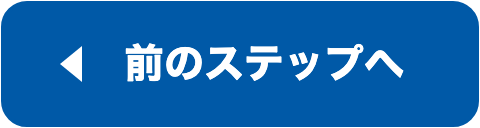](matlab:open('Step9_OptimalPowerFlow.mlx'))　　[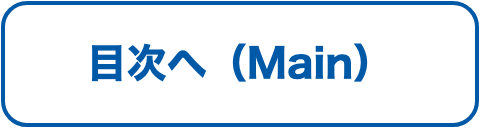](matlab:open('Main.mlx'))　　[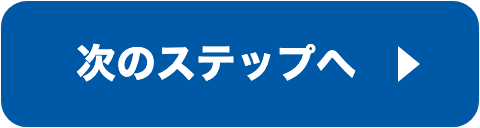](matlab:open('Step11_Setting.mlx'))